# Bootcamp Day1 Part 2

## L2 - Clinical aspects of intracranial recordings 

Fady Girgis

Phase 1 vs. Phase 2 investigations for intractibale epilepsy

Phase 1

- Semiology (lateralizing cues), tyoes of seizures, syndromes

- Scalp EEG (continuous video EEG, look for seizure onset zones, interictal dishcarges, slowing), ideal candidate has a single population of well-localized interictal epileptiform discharges (supporting presence of only one epileptogenic zone)

- Imaging (CT, MRI, DTI, fMRI, PET, SPECT)

- Neuropsychology (WADA, fMRI): epilepsy-related cognitive impairment, lateralization of language/memory, predict potential post-op benefits

- Phase 1 may suggest that there may be a surgical option for the patient, but we need more information...

Phase 2

- grids, strips, or depths (sEEG)

- sEEG: frame-based, frameless, robotic. 1) obtain pre-operative high-res MRI to play electrodes (targets and entry points, creating trajectories). want a scan with blood vessels mapped and trajectories planned that avoid vasculature. 2) merge CT and MRI info. 3) insert electrodes

Risks

- hemorrhage, stroke

- less risk with sEEG vs. subdural

Ethics

- electrode placement purely for clinical purposes based on specific hypothesis

- electroces can then be used for research purposes

- IRB approval for extra research-specific electrodes

Considerations for experimental research

- patients under stress

- experience is an asset

- space congestion in EMU

- remember, that research experiment wil not benefit patient in any way

Types of surgery

- transection (focal, eloquent) - multiple hippocampal transection

- disconnections (non-focal, non eloquent) -eg  corpus callosotomy, hemispheromoty

- resection (focal, non-elequent) - eg temporal lobectomy

- stimulation (non-focal, eloquent) - eg cranial nerve stim (VNS), thalamic stim (DBS), responsive stim

## L3 - Fundamentals of neuronal oscillations and synchrony

Arjen Stolk

Spectral analysis - deconstructing time signal into constituent frequency components

- Like GLM with oscillatory basis functions (y = b * x)

- b for components is a 2d vector on complex plane that maps onto amplitude and phase of that component (distance from origin in complex plane = amplitude, angle = phase)

- basis functions should be orthogonal

- Consequences: (1) frequencies not arbitrary (integer amount of cycles should fit into N samples of dt each). time period T -> 1/T integer frequencies can sample. (2) can only use as many basis functions as we have data points in the signal. N basis functions -> N/2 frequencies

- discrete and finite sampling constrains deconstruction

- finite = boxcar filtering of signal. discrete (ie digitization). true oscillations at freqs not sampled with FT spread their energy to the sample frequencies. each type of taper has a specific leakage profile

- tapering is used to reduce the discontinuities due to non-integer cycles in time-clipped data and reduce spectral leakage

- can use multiple tapers and combine properties

- multitapers are useful for reliable estimation of high-frequency components

- low frequency components are better estimated using single (Hanning) taper

time-frequency analysis

- divide signal into discrete time segments and computing multitaper method on each signal

- tradeoff between temporal vs. spectral resolution

- fieldtrip allows for different time window lengths, spectral smoothing for each frequency of interest chosen

wavelets

- convolution of different wavelets with signal

- wavelet width determines time-frequency resolution (often 5 cycles)

- typically slower than taper, fewer degress of freedom

## H2 - Time-frequency analysis

In this tutorial you can find information about the time-frequency  analysis of a single subject’s MEG data using a Hanning window,  multitapers and wavelets. This tutorial also shows how to visualize the  results.

Here, we will work on the MEG-language dataset, you can click [here](http://www.fieldtriptoolbox.org/tutorial/meg_language) for details on the dataset. This tutorial is a continuation from the  preprocessing tutorials. We will begin by repeating the code used to  select the trials and preprocess the data as described in the first  tutorials ([trigger based trial selection](http://www.fieldtriptoolbox.org/tutorial/preprocessing), [artifact rejection](http://www.fieldtriptoolbox.org/tutorial/artifacts)).

## Background

Calculating time-frequency representations of power is done using a  sliding time window. This can be done according to two principles:  either the time window has a fixed length independent of frequency, or  the time window decreases in length with increased frequency. For each  time window the power is calculated. Prior to calculating the power one  or more tapers are multiplied with the data. The aim of the tapers is to reduce spectral leakage and control the frequency smoothing.

If you want to know more about tapers/ window functions you can have a look at this [Wikipedia site](http://en.wikipedia.org/wiki/Window_function). Note that Hann window is another name for Hanning window used in this  tutorial. There is also a Wikipedia site about multitapers, to take a  look at it click [here](http://en.wikipedia.org/wiki/Multitaper).

## Procedure

To calculate the time-frequency analysis for the example dataset we will perform the following steps:  

- Read the data into MATLAB using [**ft_definetrial**](http://www.fieldtriptoolbox.org/reference/ft_definetrial) and [**ft_preprocessing**](http://www.fieldtriptoolbox.org/reference/ft_preprocessing)

- Compute the power values for each frequency bin and each time bin using the function [**ft_freqanalysis**](http://www.fieldtriptoolbox.org/reference/ft_freqanalysis)

- Visualize the results. This can be done by creating time-frequency plots for one ([**ft_singleplotTFR**](http://www.fieldtriptoolbox.org/reference/ft_singleplotTFR)) or several channels ([**ft_multiplotTFR**](http://www.fieldtriptoolbox.org/reference/ft_multiplotTFR)), or by creating a topographic plot for a specified time- and frequency interval ([**ft_topoplotTFR**](http://www.fieldtriptoolbox.org/reference/ft_topoplotTFR)).

## Preprocessing

The first step is to read the data using the function [**ft_preprocessing**](http://www.fieldtriptoolbox.org/reference/ft_preprocessing). With the aim to reduce boundary effects occurring at the start and the  end of the trials, it is recommended to read larger time intervals than  the time period of interest. In this example, the time of interest is  from -0.5 s to 1.5 s (t = 0 s defines the time of stimulus); however,  the script reads the data from -1.0 s to 2.0 s.

restoredefaultpath
addpath('/usr/local/MATLAB/toolboxes/fieldtrip/')
ft_defaults
addpath(genpath('/usr/local/MATLAB/toolboxes/hcn_toolbox/'))
addpath(genpath('/usr/local/MATLAB/toolboxes/fieldtrip/FieldtripBootcamp/'))

% find the interesting segments of data
cfg = [];                                           % empty configuration
cfg.dataset                 = fullfile('Fieldtrip/Subject01/Subject01.ds');       % name of CTF dataset
cfg.trialdef.eventtype      = 'backpanel trigger';
cfg.trialdef.prestim        = 1;
cfg.trialdef.poststim       = 2;
cfg.trialdef.eventvalue     = 3;                    % event value of FIC
cfg = ft_definetrial(cfg);

 In ft_definetrial at line 145

evaluating trialfunction 'ft_trialfun_general'
reading the header from 'Fieldtrip/Subject01/Subject01.ds/Subject01.res4'


 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2654
 In ft_trialfun_general at line 84
 In ft_definetrial at

 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2654
 In ft_read_event at line 513
 In ft_trialfun_gene


% remove the trials that have artifacts from the trl
cfg.trl([15, 36, 39, 42, 43, 49, 50, 81, 82, 84],:) = [];

% preprocess the data
cfg.channel   = {'MEG', '-MLP31', '-MLO12'};        % read all MEG channels except MLP31 and MLO12
cfg.demean    = 'yes';                              % do baseline correction with the complete trial

dataFIC = ft_preprocessing(cfg);

 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2654
 In ft_preprocessing at line 397

processing channel { 'MLC11' 'MLC12' 'MLC13' 'MLC14' 'MLC15' 'MLC21' 'MLC22' 'MLC23' 'MLC24' 'MLC31' 'MLC32' 'MLC33' 'MLC41' 'ML


save dataFIC dataFIC

## Time-frequency analysis

## **Hanning taper, fixed window length**

Here, we will describe how to calculate time frequency representations  using Hanning tapers. When choosing for a fixed window length procedure  the frequency resolution is defined according to the length of the time  window (delta T). The frequency resolution (delta f in figure 1) =  1/length of time window in sec (delta T in figure 1). Thus a 500 ms time window results in a 2 Hz frequency resolution (1/0.5 sec= 2 Hz) meaning that power can be calculated for 2 Hz, 4 Hz, 6 Hz etc. An integer  number of cycles must fit in the time window.

In the following example a time window with length 500 ms is applied.

cfg              = [];
cfg.output       = 'pow';
cfg.channel      = 'MEG';
cfg.method       = 'mtmconvol';
cfg.taper        = 'hanning';
cfg.foi          = 2:2:30;                         % analysis 2 to 30 Hz in steps of 2 Hz
cfg.t_ftimwin    = ones(length(cfg.foi),1).*0.5;   % length of time window = 0.5 sec
cfg.toi          = -0.5:0.05:1.5;                  % time window "slides" from -0.5 to 1.5 sec in steps of 0.05 sec (50 ms)
TFRhann = ft_freqanalysis(cfg, dataFIC);

the input is raw data with 149 channels and 77 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 77, frequency 15 (30.00 Hz), 1 tapers

the call to "ft_freqanalysis" took 3 seconds and required the additional allocation of an estimated 0 MB


Regardless of the method used for calculating the TFR, the output format is identical. It is a structure with the following element

TFRhann

TFRhann = struct with fields:
        label: {149×1 cell}
       dimord: 'chan_freq_time'
         freq: [2 4 6 8 10 12 14 16 18 20 22 24 26 28 30]
         time: [1×41 double]
    powspctrm: [149×15×41 double]
         elec: [1×1 struct]
         grad: [1×1 struct]
          cfg: [1×1 struct]


The element TFRhann.powspctrm contains the temporal evolution of the raw power values for each specified frequency.

## Visualization

This part of the tutorial shows how to visualize the results of any type of time-frequency analysis.

To visualize the event-related power changes, a normalization with  respect to a baseline interval will be performed. There are two  possibilities for normalizing: (a) subtracting, for each frequency, the  average power in a baseline interval from all other power values. This  gives, for each frequency, the absolute change in power with respect to  the baseline interval. (b) expressing, for each frequency, the raw power values as the relative increase or decrease with respect to the power  in the baseline interval. This means active period/baseline. Note that  the relative baseline is expressed as a ratio; i.e. no change is  represented by 1.

There are three ways of graphically representing the data: 1)  time-frequency plots of all channels, in a quasi-topographical layout,  2) time-frequency plot of an individual channel (or average of several  channels), 3) topographical 2-D map of the power changes in a specified  time-frequency interval.

To plot the TFRs from all the sensors use the function [**ft_multiplotTFR**](http://www.fieldtriptoolbox.org/reference/ft_multiplotTFR). Settings can be adjusted in the cfg structure. For example.

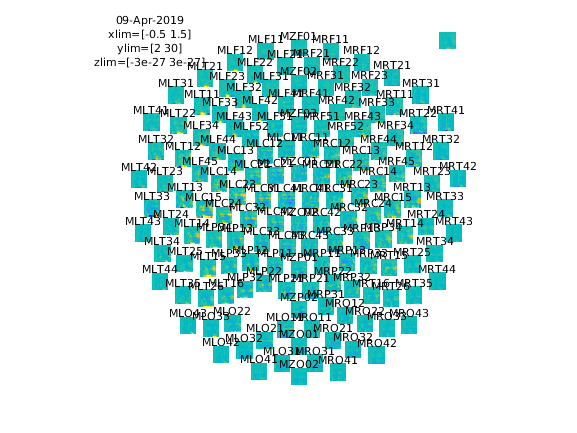

the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 3 MB
reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_multiplotTFR" took 7 seconds and required the additional allocation of an estimated 4 MB


cfg = [];
cfg.baseline     = [-0.5 -0.1];
cfg.baselinetype = 'absolute';
cfg.zlim         = [-3e-27 3e-27];
cfg.showlabels   = 'yes';
cfg.layout       = 'CTF151_helmet.mat';
figure
ft_multiplotTFR(cfg, TFRhann);

Note that by using the options cfg.baseline and cfg.baselinetype when calling plotting functions, baseline correction can be applied to the  data. Baseline correction can also be applied directly by calling [**ft_freqbaseline**](http://www.fieldtriptoolbox.org/reference/ft_freqbaseline). You can combine the various visualisation options/functions  interactively to explore your data. Currently, this is the default  ploting behavior because the configuration option cfg.interactive=’yes’  is activated unless you explicitly select cfg.interactive=’no’ before  calling [**ft_multiplotTFR**](http://www.fieldtriptoolbox.org/reference/ft_multiplotTFR) to deactivate it. See also the [plotting tutorial](http://www.fieldtriptoolbox.org/tutorial/plotting) for more details.

An interesting effect seems to be present in the TFR of sensor MRC15. To make a plot of a single channel use the function [**ft_singleplotTFR**](http://www.fieldtriptoolbox.org/reference/ft_singleplotTFR).

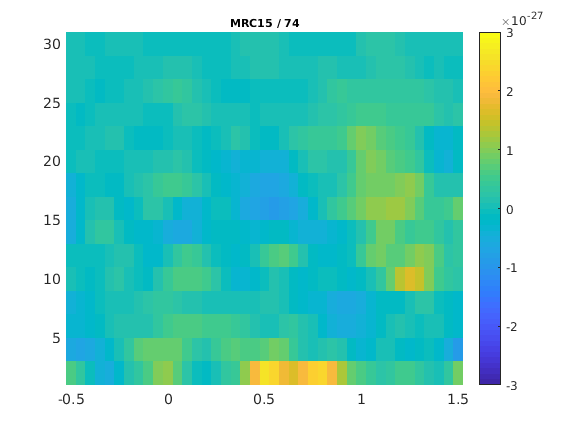

the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_singleplotTFR" took 1 seconds and required the additional allocation of an estimated 1 MB


cfg = [];
cfg.baseline     = [-0.5 -0.1];
cfg.baselinetype = 'absolute';
cfg.maskstyle    = 'saturation';
cfg.zlim         = [-3e-27 3e-27];
cfg.channel      = 'MRC15';
figure
ft_singleplotTFR(cfg, TFRhann);

From the figure one can see that there is an increase in power around  15-20 Hz in the time interval 0.9 to 1.3 s after stimulus onset. To show the topography of the beta increase use the function [**ft_topoplotTFR**](http://www.fieldtriptoolbox.org/reference/ft_topoplotTFR).

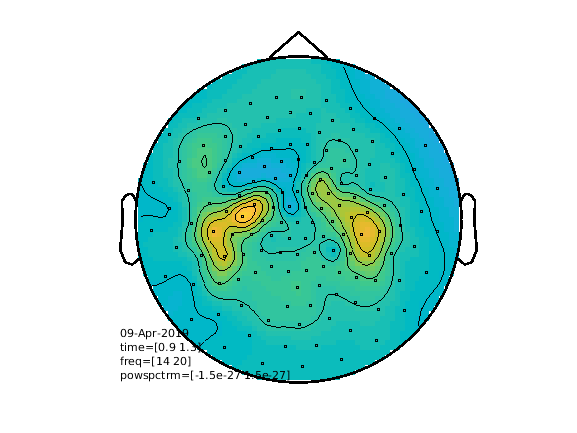

creating layout from data.grad
creating layout for ctf151 system
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_topoplotTFR" took 1 seconds and required the additional allocation of an estimated 1 MB


cfg = [];
cfg.baseline     = [-0.5 -0.1];
cfg.baselinetype = 'absolute';
cfg.xlim         = [0.9 1.3];
cfg.zlim         = [-1.5e-27 1.5e-27];
cfg.ylim         = [15 20];
cfg.marker       = 'on';
figure
ft_topoplotTFR(cfg, TFRhann);

Exercise 1

Plot the power with respect to a relative baseline

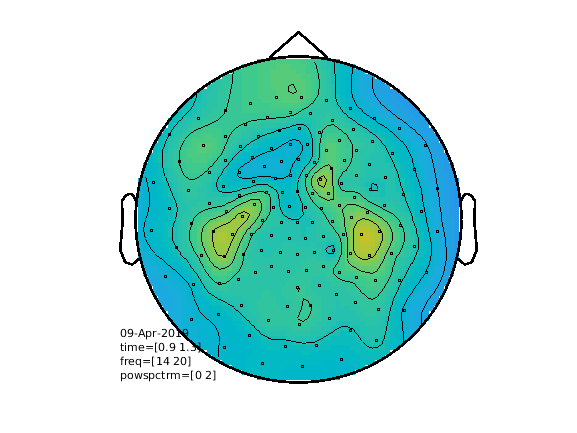

creating layout from data.grad
creating layout for ctf151 system
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_topoplotTFR" took 1 seconds and required the additional allocation of an estimated 1 MB


cfg = [];
cfg.baseline     = [-0.5 -0.1];
cfg.baselinetype = 'relative';
cfg.xlim         = [0.9 1.3];
cfg.zlim         = [0 2.0];
cfg.ylim         = [15 20];
cfg.marker       = 'on';
figure
ft_topoplotTFR(cfg, TFRhann);

Exercise 2

Plot the TFR of sensor MLC24.

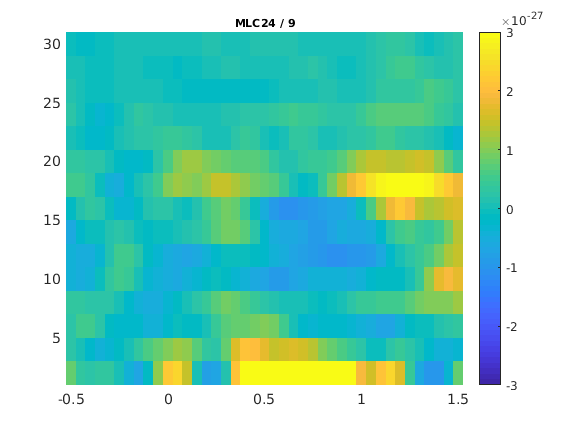

the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_singleplotTFR" took 1 seconds and required the additional allocation of an estimated 1 MB


cfg = [];
cfg.baseline     = [-0.5 -0.1];
cfg.baselinetype = 'absolute';
cfg.maskstyle    = 'saturation';
cfg.zlim         = [-3e-27 3e-27];
cfg.channel      = 'MLC24';
figure
ft_singleplotTFR(cfg, TFRhann);

## **Hanning taper, frequency dependent window length**

It is also possible to calculate the TFRs with respect to a time  window that varies with frequency. Typically the time window gets  shorter with an increase in frequency. The main advantage of this  approach is that the temporal smoothing decreases with higher  frequencies; however, this is on the expense of frequency smoothing. We  will here show how to perform this analysis with a Hanning window. The  approach is very similar to wavelet analysis. A wavelet analysis  performed with a Morlet wavelet mainly differs by applying a Gaussian  shaped taper.

The analysis is best done by first selecting the numbers of cycles  per time window which will be the same for all frequencies. For instance if the number of cycles per window is 7, the time window is 1000 ms for 7 Hz (1/7 x 7 cycles); 700 ms for 10 Hz (1/10 x 7 cycles) and 350 ms  for 20 Hz (1/20 x 7 cycles). The frequency can be chosen arbitrarily -  however; too fine a frequency resolution is just going to increase the  redundancy rather than providing new information.

Below is the configuration for a 7-cycle time window. The calculation is only done for one sensor (MRC15) but it can of course be extended to all sensors.

cfg              = [];
cfg.output       = 'pow';
cfg.channel      = 'MRC15';
cfg.method       = 'mtmconvol';
cfg.taper        = 'hanning';
cfg.foi          = 2:1:30;
cfg.t_ftimwin    = 7./cfg.foi;  % 7 cycles per time window
cfg.toi          = -0.5:0.05:1.5;
TFRhann7 = ft_freqanalysis(cfg, dataFIC);

the input is raw data with 149 channels and 77 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 77, frequency 29 (30.00 Hz), 1 tapers

the call to "ft_freqanalysis" took 3 seconds and required the additional allocation of an estimated 1 MB


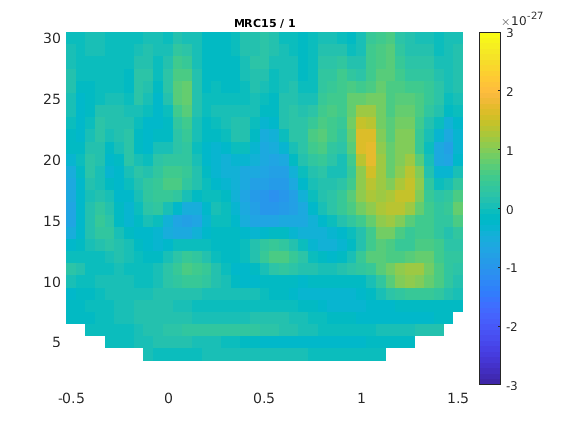

the input is freq data with 1 channels, 29 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_singleplotTFR" took 1 seconds and required the additional allocation of an estimated 0 MB



cfg              = [];
cfg.baseline     = [-0.5 -0.1];
cfg.baselinetype = 'absolute';
cfg.maskstyle    = 'saturation';
cfg.zlim         = [-3e-27 3e-27];
cfg.channel      = 'MRC15';
cfg.interactive  = 'no';
figure
ft_singleplotTFR(cfg, TFRhann7);

Note the boundary effects for lower frequencies (the white time  frequency points in the plot). There is no power value calculated for  these time frequency points. The power value is assigned to the middle  time point in the time window. For example for 2 Hz the time window has a length of 3.5 sec (1/2 _ 7 cycles = 3.5 sec), this does not fit in the 3 sec window that is preprocessed and therefore there is no data point  here. For 5 Hz the window has a length of 1.4 sec (1/5 _ 7 cycles = 1.4  sec). We preprocessed data between t = -1 sec and t = 2 sec so the first power value is assigned to t= -0.3 (since -1 + (0.5 * 1.4) = -0.3).  Because of these boundary effects it is important to apply [**ft_freqanalysis **](http://www.fieldtriptoolbox.org/reference/ft_freqanalysis) to a larger time window to get all the time frequency points for your time window of interest.

Exercise 3

Adjust the length of the time-window and thereby degree of smoothing. Use [**ft_singleplotTFR**](http://www.fieldtriptoolbox.org/reference/ft_singleplotTFR) to show the results.

4 cycles per time window:

cfg              = [];
cfg.output       = 'pow';
cfg.channel      = 'MRC15';
cfg.method       = 'mtmconvol';
cfg.taper        = 'hanning';
cfg.foi          = 2:1:30;
cfg.t_ftimwin    = 4./cfg.foi;
cfg.toi          = -0.5:0.05:1.5;
TFRhann4 = ft_freqanalysis(cfg, dataFIC);

the input is raw data with 149 channels and 77 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 77, frequency 29 (30.00 Hz), 1 tapers

the call to "ft_freqanalysis" took 2 seconds and required the additional allocation of an estimated 0 MB


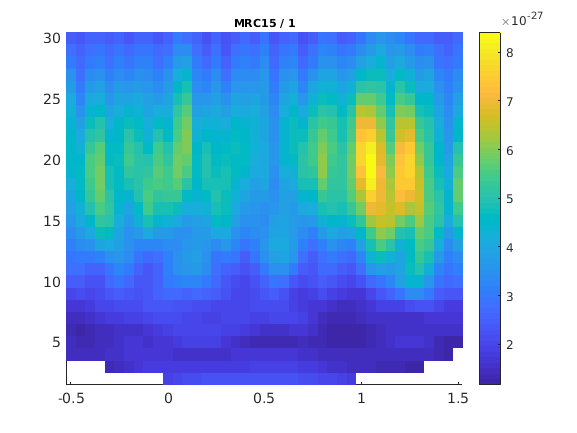

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_singleplotTFR" took 0 seconds and required the additional allocation of an estimated 0 MB



figure
ft_singleplotTFR(cfg, TFRhann4);

5 cycles per time window:

cfg.t_ftimwin    = 5./cfg.foi;
TFRhann5 = ft_freqanalysis(cfg, dataFIC);

the input is raw data with 149 channels and 77 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 77, frequency 29 (30.00 Hz), 1 tapers

the call to "ft_freqanalysis" took 2 seconds and required the additional allocation of an estimated 0 MB


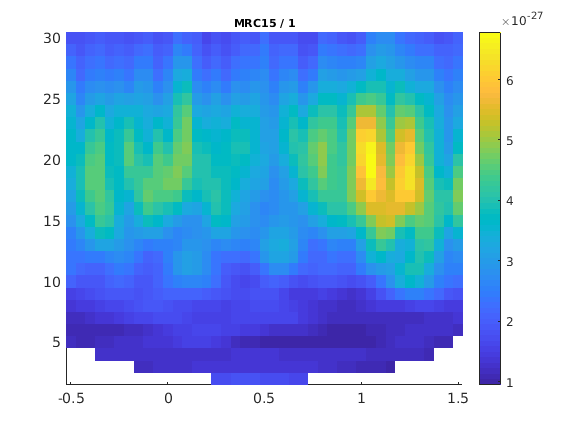

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_singleplotTFR" took 0 seconds and required the additional allocation of an estimated 0 MB



figure
ft_singleplotTFR(cfg, TFRhann5);

10 cycles per time window:

cfg.t_ftimwin    = 10./cfg.foi;
TFRhann10 = ft_freqanalysis(cfg, dataFIC);

the input is raw data with 149 channels and 77 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 77, frequency 29 (30.00 Hz), 1 tapers

the call to "ft_freqanalysis" took 1 seconds and required the additional allocation of an estimated 0 MB


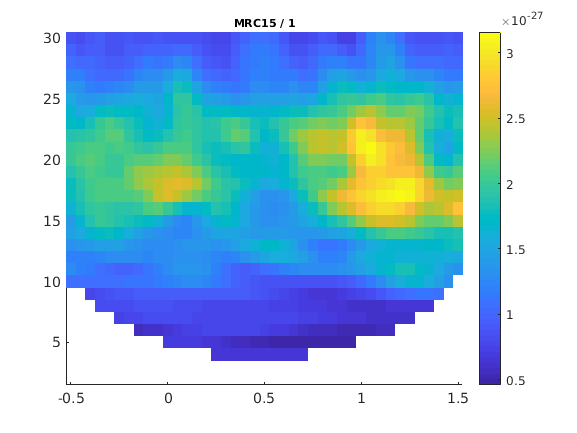

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_singleplotTFR" took 0 seconds and required the additional allocation of an estimated 0 MB



figure
ft_singleplotTFR(cfg, TFRhann10);

## Multitapers

Multitapers are typically used in order to achieve better control  over the frequency smoothing. More tapers for a given time window will  result in greater smoothing. High frequency smoothing has been shown to  be particularly advantageous when dealing with electrophysiological  brain signals above 30 Hz. Oscillatory gamma activity (30-100 Hz) is  quite broad band and thus analysis of such signals benefit from  multitapering. For signals lower than 30 Hz it is recommend to use only a single taper, e.g. a Hanning taper as shown above (beware that in the  example below multitapers are used to analyze low frequencies because  there are no effects in the gamma band in this dataset).

Time-frequency analysis based on multitapers can be performed by the function [**ft_freqanalysis**](http://www.fieldtriptoolbox.org/reference/ft_freqanalysis). The function uses a sliding time window for which the power is  calculated for a given frequency. Prior to calculating the power by  discrete Fourier transformations the data are ‘tapered’. Several  orthogonal tapers might be used for each time window. The power is  calculated for each tapered data segment and then combined. In the  example below we apply a time window which gradually becomes shorter for higher frequencies (similar to wavelet techniques). The arguments for  the chosen parameters are as follows

- cfg.foi, the frequencies of interest, here from 1 Hz to 30 Hz in  steps of 2 Hz. The step size could be decreased at the expense of  computation time and redundancy.

- cfg.toi, the time-interval of interest. This vector determines the center times for the time windows for which the power values should be  calculated. The setting cfg.toi = -0.5:0.05:1.5 results in power values  from -0.5 to 1.5 s in steps of 50 ms. A finer time resolution will give  redundant information and longer computation times, but a smoother  graphical output.

- cfg.t_ftimwin is the length of the sliding time-window in seconds  (= tw). We have chosen cfg.t_ftimwin = 5./cfg.foi, i.e. 5 cycles per  time-window. When choosing this parameter it is important that a full  number of cycles fit within the time-window for a given frequency.

- cfg.tapsmofrq determines the width of frequency smoothing in Hz  (= fw). We have chosen cfg.tapsmofrq = cfg.foi*0.4, i.e. the smoothing  will increase with frequency. Specifying larger values will result in  more frequency smoothing. For less smoothing you can specify smaller  values, however, the following relation (determined by the Shannon  number) must hold (see Percival and Walden, 1993):    K = 2*tw*fw-1, where K is required to be larger than 0.  

K is the number of multitapers applied; the more tapers the greater the smoothing.

cfg = [];
cfg.output     = 'pow';
cfg.channel    = 'MEG';
cfg.method     = 'mtmconvol';
cfg.foi        = 1:2:30;
cfg.t_ftimwin  = 5./cfg.foi;
cfg.tapsmofrq  = 0.4 *cfg.foi;
cfg.toi        = -0.5:0.05:1.5;
TFRmult = ft_freqanalysis(cfg, dataFIC);

the input is raw data with 149 channels and 77 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 77, frequency 15 (29.00 Hz), 3 tapers

the call to "ft_freqanalysis" took 25 seconds and required the additional allocation of an estimated 2 MB


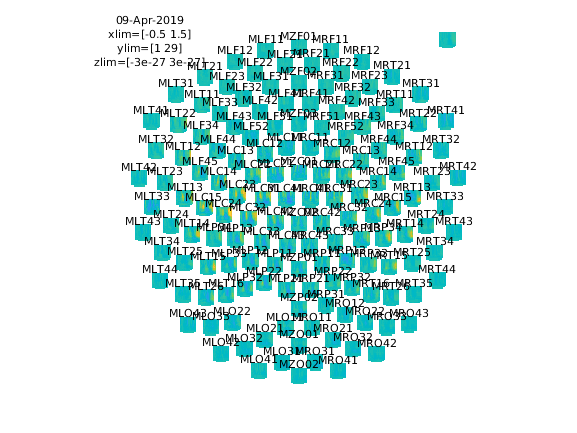

the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_multiplotTFR" took 10 seconds and required the additional allocation of an estimated 1 MB



cfg = [];
cfg.baseline     = [-0.5 -0.1];
cfg.baselinetype = 'absolute';
cfg.zlim         = [-3e-27 3e-27];
cfg.showlabels   = 'yes';
cfg.layout       = 'CTF151_helmet.mat';
figure
ft_multiplotTFR(cfg, TFRmult)

## Morlet wavelets

An alternative to calculating TFRs with the multitaper method is to  use Morlet wavelets. The approach is equivalent to calculating TFRs with time windows that depend on frequency using a taper with a Gaussian  shape. The commands below illustrate how to do this. One crucial  parameter to set is cfg.width. It determines the width of the wavelets  in number of cycles. Making the value smaller will increase the temporal resolution at the expense of frequency resolution and vice versa. The  spectral bandwidth at a given frequency F is equal to F/width*2 (so, at 30 Hz and a width of 7, the spectral bandwidth is 30/7*2 = 8.6 Hz) while the wavelet duration is equal to width/F/pi (in this  case, 7/30/pi = 0.074s = 74ms) ((Tallon-Baudry and Bertrand (1999)  Oscillatory gamma activity in humans and its role in object  representation. Trends Cogn Sci. 3(4):151-162)).

Calculate TFRs using Morlet wavelet

cfg = [];
cfg.channel    = 'MEG';
cfg.method     = 'wavelet';
cfg.width      = 7;
cfg.output     = 'pow';
cfg.foi        = 1:2:30;
cfg.toi        = -0.5:0.05:1.5;
TFRwave = ft_freqanalysis(cfg, dataFIC);

the input is raw data with 149 channels and 77 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 77, frequency 15 (29.00 Hz)

the call to "ft_freqanalysis" took 12 seconds and required the additional allocation of an estimated 10 MB


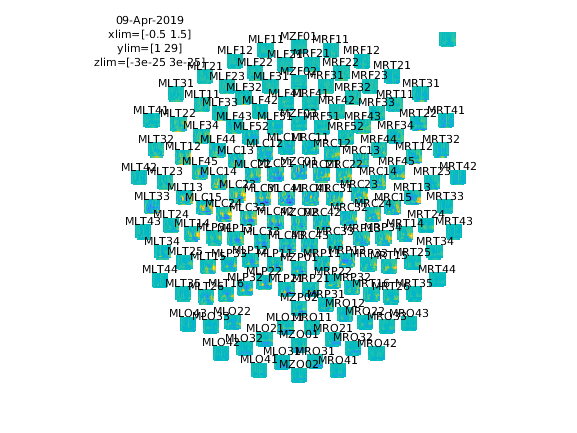

the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_multiplotTFR" took 12 seconds and required the additional allocation of an estimated 0 MB



cfg = [];
cfg.baseline     = [-0.5 -0.1];
cfg.baselinetype = 'absolute';
cfg.zlim         = [-3e-25 3e-25];
cfg.showlabels   = 'yes';
cfg.layout       = 'CTF151_helmet.mat';
figure
ft_multiplotTFR(cfg, TFRwave)

Exercise 4

Adjust cfg.width and see how the TFRs change.

% width = 4
cfg = [];
cfg.channel    = 'MEG';
cfg.method     = 'wavelet';
cfg.width      = 4;
cfg.output     = 'pow';
cfg.foi        = 1:2:30;
cfg.toi        = -0.5:0.05:1.5;
TFRwave = ft_freqanalysis(cfg, dataFIC);

the input is raw data with 149 channels and 77 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 77, frequency 15 (29.00 Hz)

the call to "ft_freqanalysis" took 11 seconds and required the additional allocation of an estimated 14 MB


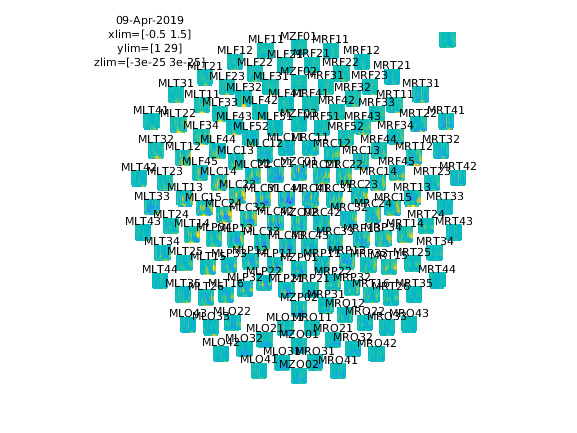

the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_multiplotTFR" took 16 seconds and required the additional allocation of an estimated 0 MB



cfg = [];
cfg.baseline     = [-0.5 -0.1];
cfg.baselinetype = 'absolute';
cfg.zlim         = [-3e-25 3e-25];
cfg.showlabels   = 'yes';
cfg.layout       = 'CTF151_helmet.mat';
figure
ft_multiplotTFR(cfg, TFRwave)


% width = 10
cfg = [];
cfg.channel    = 'MEG';
cfg.method     = 'wavelet';
cfg.width      = 10;
cfg.output     = 'pow';
cfg.foi        = 1:2:30;
cfg.toi        = -0.5:0.05:1.5;
TFRwave = ft_freqanalysis(cfg, dataFIC);

the input is raw data with 149 channels and 77 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 77, frequency 15 (29.00 Hz)

the call to "ft_freqanalysis" took 3 seconds and required the additional allocation of an estimated 7 MB


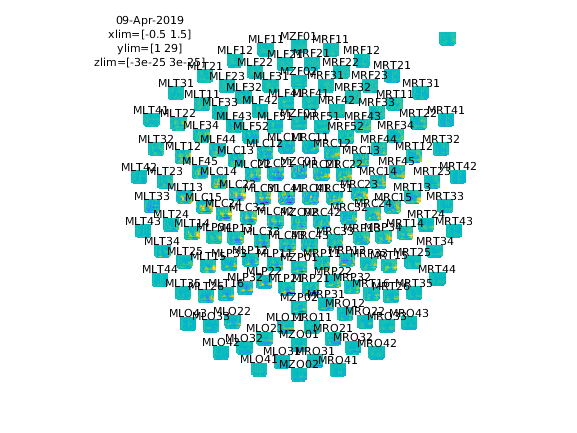

the input is freq data with 149 channels, 15 frequencybins and 41 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_multiplotTFR" took 16 seconds and required the additional allocation of an estimated 0 MB



cfg = [];
cfg.baseline     = [-0.5 -0.1];
cfg.baselinetype = 'absolute';
cfg.zlim         = [-3e-25 3e-25];
cfg.showlabels   = 'yes';
cfg.layout       = 'CTF151_helmet.mat';
figure
ft_multiplotTFR(cfg, TFRwave)

## Visualization of iEEG data

Needs to be individualized/mapped to individual subjects and individual electrode localizations

Common reference - requires that reference electrode is relatively silent (elsewise its activity will show up in all other channels)

Average reference - good idea if activity in electrodes is well-behaved (eg, no electrodes have large artifacts, noise across electrodes is uncorrelated)

Bipolar reference - one of the most focal references you can easily achieve